# Detection of ships on satellite images using YOLOv2 deep learning

The development of maritime autonomous surface ships (MASS) has rapidly emerged in recent years worldwide. Besides many navigation-, regulatory-, cyber-security and other challenges, sensory networks and massive data processing for increasing situational awareness of MASS present one of the major challenges in autonomous maritime shipping. In this example, the topic of extracting useful information from satellite images is discussed with the aim to present the basic workflow of developing a simple deep learning based ship detector, which can be included in a broad range of situational awareness sensors of MASS systems.

Satellite images from the [Airbus Ship Detection Challenge database](https://www.kaggle.com/c/airbus-ship-detection/data) are used and are arranged in two folders: train and test. 

- Train folder includes 100 images with ships, and these images are used for deep learning detector training. 

- Test folder includes additional 50 images that are used after training to check the generalization performance of the developed detector.

This example is based on MATLAB code [Object Detection Using YOLO v2 Deep Learning](https://www.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v2.html) which applies transfer learning as a solution approach.

[Transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) provides a very fast way of deep learning and utilizes a pretrained deep network as a starting point to learn a new task, which is then fine-tuned to a new task. In this case, usually, also a smaller number of training images is required to solve the task. 

The task of this example is to use the dataset of available training images, and construct the ship detector using deep learning and transfer learning. The objective for the developed detector is then to acquire new (test) images and recognize and locate the ships on the images.

2022 © [Primož Potočnik](mailto://primoz.potocnik@fs.uni-lj.si)

## Solution approach

The presented solution approach comprises the following steps:

- Using [Image Labeler](https://www.mathworks.com/help/vision/ref/imagelabeler-app.html) for labeling of ship segments.

- Data preprocessing (creating datastore and resizing images).

- Applying pretrained [ResNet50](https://www.mathworks.com/help/deeplearning/ref/resnet50.html) deep network as a feature extractor.

- Creating and training [YOLO](https://www.mathworks.com/help/vision/ug/create-yolo-v2-object-detection-network.html) object detection network.

- Evaluating YOLO detector on train and test images.

## **Settings**

close all, clear all, clc, format compact, warning off

% folders
dataFolder   = 'data/'; % data folder
trainFolder  = [dataFolder 'train/']; % ship images for training
testFolder   = [dataFolder 'test/' ]; % ship images for testing

% pretrained YOLOv2 network to download
pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/yolov2ResNet50VehicleExample_19b.mat';

% my trained YOLOv2 detector for ships (after training)
trainedYOLO   = [dataFolder 'YOLOv2detector.mat'];

% YOLO input size
inputSize     = [224 224 3];

## Use Image Labeler for labeling of ship segments

% show ImageLabeler 
openImageLabeler = false;

cd(dataFolder)
if openImageLabeler 
  imageLabeler('imageLabelingSession.mat');
end

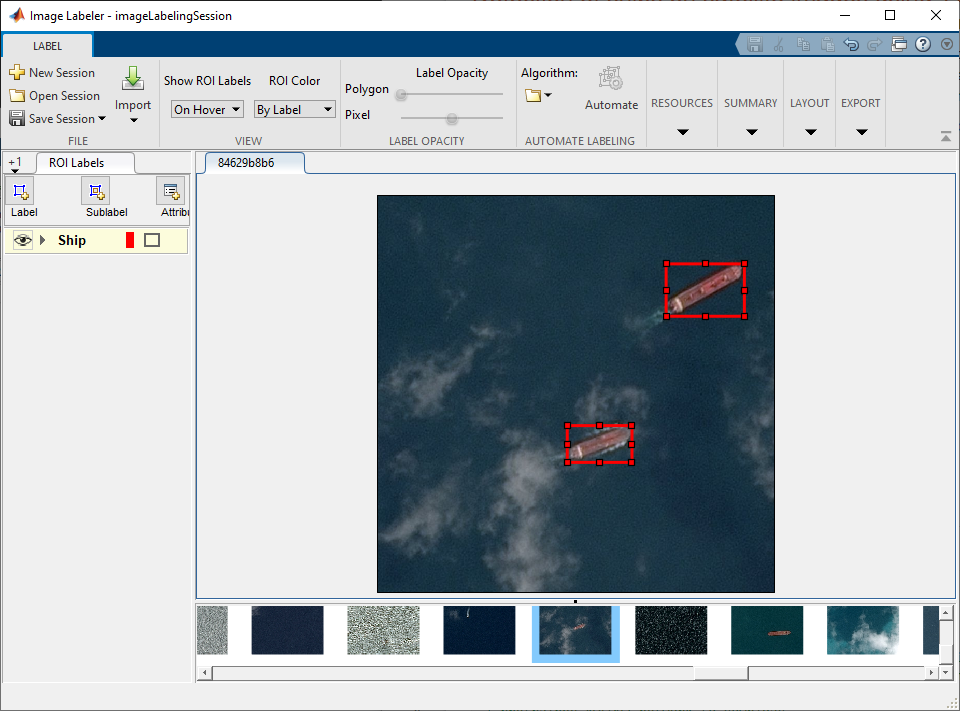

**Working with Image Labeler**

- Define label 'Ship'

- Manual labeling of ship segments (bounding boxes must be non-empty)

- Save session 'imageLabelingSession.mat'

- Save labeling results: Export labels to file 'imageLabelsResults.mat'

% load table which is a result of ImageLabeler
load('imageLabelsResults.mat')
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [1×5 table]
           LabelData: [100×1 table]

'gTruth' shows information about 100 labeled images, used to train YOLO ship detector

gTruth.LabelDefinitions

ans = 1×5 table
      Name        Type       LabelColor      Group      Description
    ________    _________    ___________    ________    ___________
    {'Ship'}    Rectangle    1    0    0    {'None'}    {0×0 char} 

gTruth.LabelData

ans = 100×1 table
           Ship        
    ___________________
    {[ 492 18 187 146]}
    {2×4 double       }
    {[281 496 255 142]}
    {[  552 24 217 84]}
    {[376 642 178 127]}
    {[  244 361 73 82]}
    {[  601 334 46 33]}
    {[129 351 120 242]}
    {[ 98 387 158 114]}
    {[  212 423 40 95]}
    {[  35 174 83 203]}
    {2×4 double       }
    {2×4 double       }
    {[ 437 666 40 103]}
    {3×4 double       }
    {[ 195 593 99 160]}


% back to main folder
cd ../

## Data preprocessing

### Create datastore for loading the images and labels

% Use imageDatastore and boxLabelDatastore to create datastores for loading the images and label data
imds = imageDatastore(gTruth.DataSource.Source); % image file names
blds = boxLabelDatastore(gTruth.LabelData); % labels

% combine images and labels
combinedData = combine(imds, blds);

% number of images for training
N_images = height(gTruth.LabelData)

N_images = 100

### Preprocess training data for YOLO

The training images used in this example are bigger than 224-by-224, so we must resize the images in a preprocessing step prior to training. Function [transform](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html) is used to preprocess training data.

% Preprocess the data (resize)
preprocessedData = transform(combinedData,@(data)preprocessData(data,inputSize));

### Show all transformed labeled images

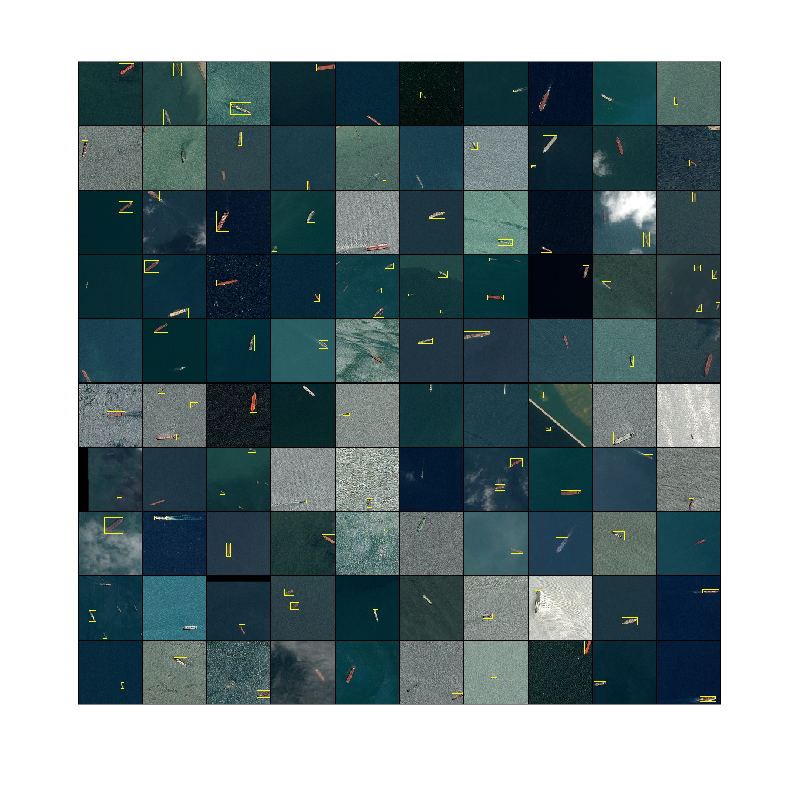

% read transformed images
clear annotatedImage*
for i = 1:N_images
  data = read(preprocessedData); % reading in order
  % add bounding box to image
  image = data{1};
  bbox  = data{2};
  annotatedImages{i} = insertShape(image,'Rectangle',bbox);
end

% show transformed images
montage(annotatedImages, 'BorderSize',1)

### Show individual transformed labeled image

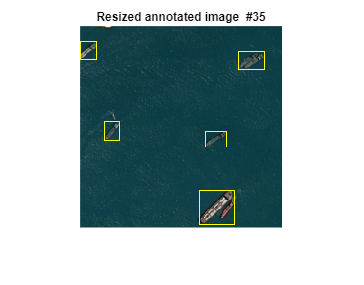

% show selected transformed image
pick_image = 35;

imshow(annotatedImages{pick_image})
title(['Resized annotated image  #' num2str(pick_image)])

## Use pretrained ResNet50 deep network as feature extractor

The pretrained [ResNet-50](https://www.mathworks.com/matlabcentral/fileexchange/64626-deep-learning-toolbox-model-for-resnet-50-network) deep network model has been trained on a subset of the ImageNet database. ResNet-50 won the ImageNet Large-Scale Visual Recognition Challenge (ILSVRC) competition in 2015. The model is trained on more than a million images, has 177 layers in total, corresponding to a 50 layer residual network, and can classify images into 1000 object categories. 

Use MATLAB Add-Ons to load the pretrained [Deep Learning Toolbox Model for ResNet-50 Network](https://www.mathworks.com/matlabcentral/fileexchange/64626-deep-learning-toolbox-model-for-resnet-50-network). Check the resnet50 model:

resnet50

ans =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}

Now, load a pretrained ResNet-50 model as feature extrractor:

featureExtractionNetwork = resnet50;


Select 'activation_40_relu' as the feature extraction layer to replace the layers after 'activation_40_relu' with the detection subnetwork. This feature extraction layer outputs feature maps that are downsampled by a factor of 16. This amount of downsampling is a good trade-off between spatial resolution and the strength of the extracted features, as features extracted further down the network encode stronger image features at the cost of spatial resolution. Choosing the optimal feature extraction layer requires empirical analysis.

featureLayer = 'activation_40_relu';

View the feature extraction layer in the ResNet-50 network architecture:

showDeepNetworkDesigner = false;

if showDeepNetworkDesigner 
  deepNetworkDesigner(featureExtractionNetwork)
end

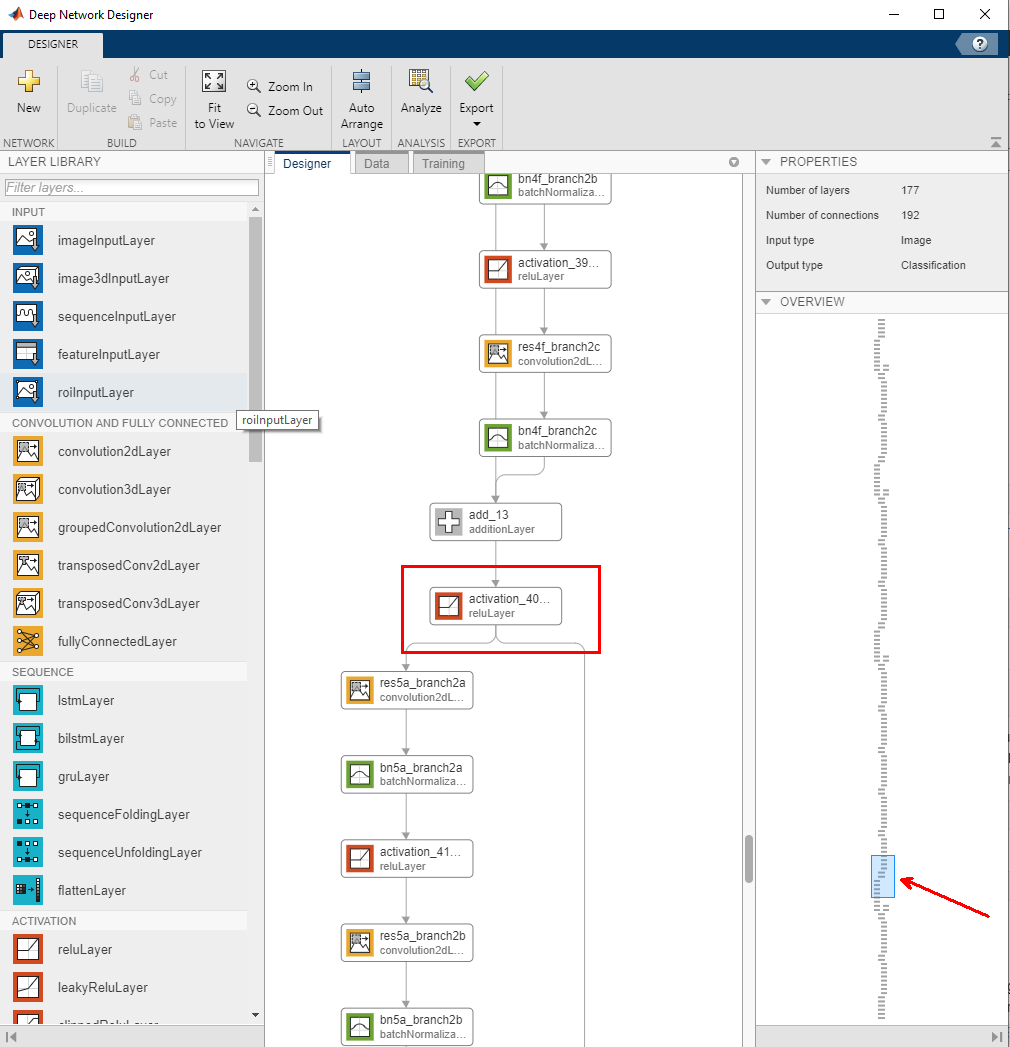

### Freeze weights of a feature extractor network

Optionally, you can "freeze" the weights of feature extractor layers by setting the learning rates in those layers to zero. During training, `trainNetwork` does not update the parameters of the frozen layers. Because the gradients of the frozen layers do not need to be computed, freezing the weights of many initial layers can significantly speed up network training. If the new data set is small, then freezing earlier network layers can also prevent those layers from overfitting to the new data set. 

See [Train Deep Learning Network to Classify New Images](https://www.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html).

## Create YOLO object detection network

[YOLO object detection](https://www.mathworks.com/help/vision/ug/create-yolo-v2-object-detection-network.html) algorithm employs convolutional neural networks (CNN) to detect objects in real-time. YOLO is an abbreviation for the term ‘You Only Look Once’ which suggests, that the algorithm requires only a single forward propagation through a neural network to detect objects. This algorithm is popular because of its speed and accuracy. It has been used in various applications to detect traffic signals, people, parking meters, and animals.

Specify the network input size (inputSize). When choosing the network input size, consider the minimum size required by the network itself, the size of the training images, and the computational cost incurred by processing data at the selected size. When feasible, choose a network input size that is close to the size of the training image and larger than the input size required for the network. To reduce the computational cost of running the example, specify a network input size of [224 224 3], which is the minimum size required to run the network.

%inputSize = [224 224 3]; % already defined in Settings section

Specify the number of classes (numClasses) for YOLO network:

numClasses = 1; % number of object classes to detect

Next, use [estimateAnchorBoxes](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) (Computer Vision Toolbox) to estimate anchor boxes based on the size of objects in the training data. To account for the resizing of the images before training, resize the training data for estimating anchor boxes. Use transform to preprocess the training data, then define the number of anchor boxes and estimate the anchor boxes. Resize the training data to the input image size of the network using the supporting function preprocessData. See the reference to [Anchor Boxes for Object Detection](https://www.mathworks.com/help/vision/ug/anchor-boxes-for-object-detection.html)

numAnchors = 7;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(preprocessedData, numAnchors);

Finally, create the YOLO v2 object detection network by **using the ResNet50 feature extractor**.

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer)

lgraph =   LayerGraph with properties:

         Layers: [150×1 nnet.cnn.layer.Layer]
    Connections: [162×2 table]
     InputNames: {'input_1'}
    OutputNames: {'yolov2OutputLayer'}

Use [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) and [Analyze Network](https://www.mathworks.com/help/deeplearning/ref/analyzenetwork.html) functions to visualize the resulting YOLO v2 image detector architecture:

showDeepNetworkDesigner = false;

if showDeepNetworkDesigner 
  deepNetworkDesigner(lgraph)
  analyzeNetwork(lgraph)
end

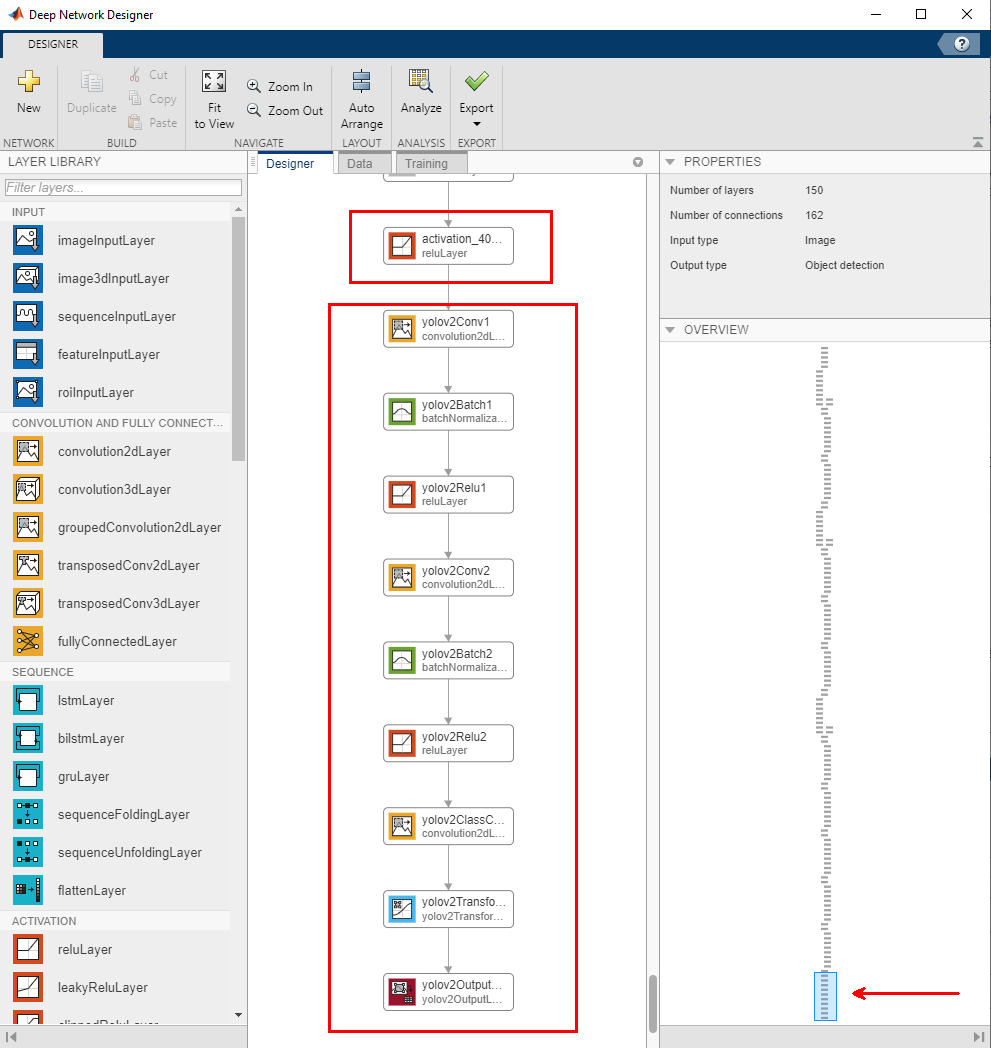

## Train YOLO object detector

% execute training of a YOLO deep network
doTraining    = false;

% Specify network training options 
options = trainingOptions('sgdm', ...
        'MiniBatchSize',12, ....
        'InitialLearnRate',1e-3, ...
        'MaxEpochs',120, ... 
        'ValidationData',preprocessedData);

% Use trainYOLOv2ObjectDetector (Computer Vision Toolbox) function to train YOLO v2 object detector if doTraining is true
if doTraining 
  disp('TRAIN YOLO...')
  [detector,info] = trainYOLOv2ObjectDetector(preprocessedData,lgraph,options);
  save(trainedYOLO, 'detector')
% Otherwise, load the pretrained network
else
  disp('LOAD YOLO...')
  load(trainedYOLO)
end

LOAD YOLO...


% Show & analyze YOLO network
close all
analyzeNetwork(lgraph);


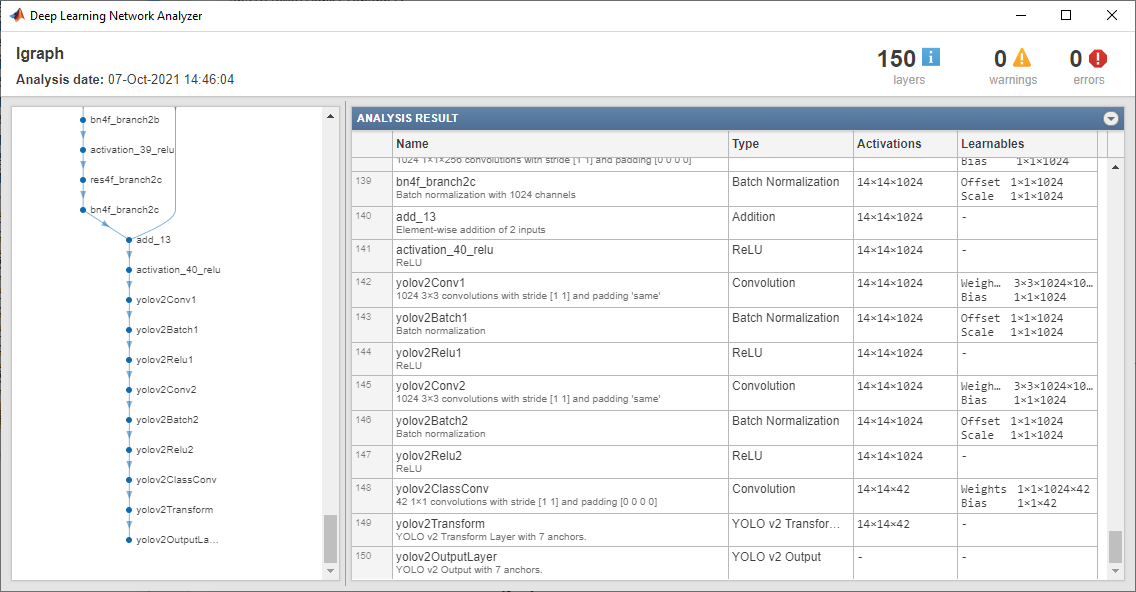

% display layer information
lgraph.Layers

ans =   150×1 Layer array with layers:

     1   'input_1'              Image Input                224×224×3 images with 'zerocenter' normalization
     2   'conv1'                Convolution                64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'             Batch Normalization        Batch normalization with 64 channels
     4   'activation_1_relu'    ReLU                       ReLU
     5   'max_pooling2d_1'      Max Pooling                3×3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'       Convolution                64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'bn2a_branch2a'        Batch Normalization        Batch normalization with 64 channels
     8   'activation_2_relu'    ReLU                       ReLU
     9   'res2a_branch2b'       Convolution                64 3×3×64 convolutions wit

## Results

### Evaluate YOLO detector on TRAIN images

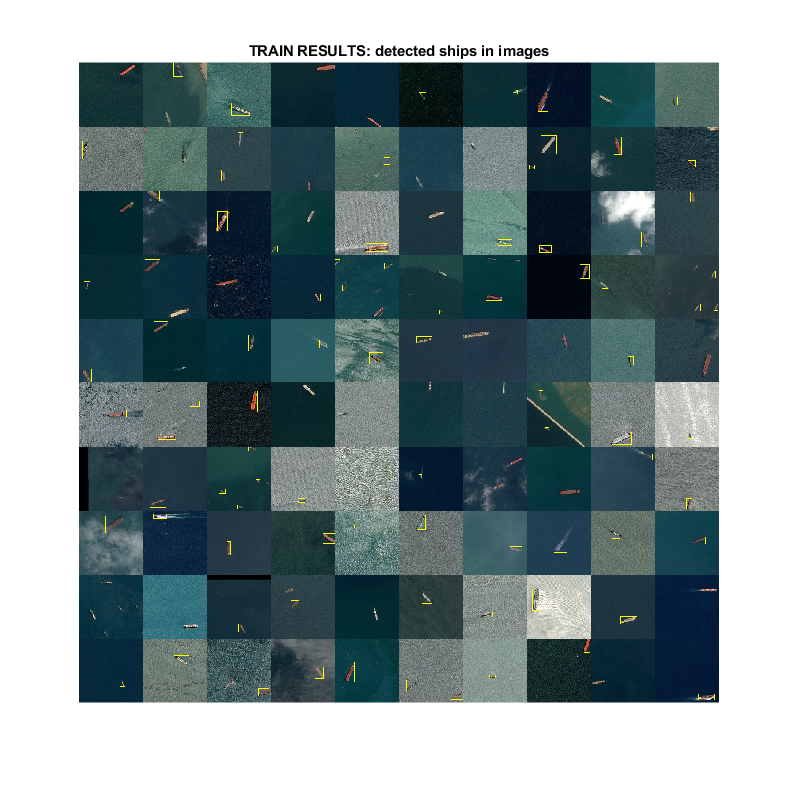

close all, warning on

% run detector on images
detectionResults = detect(detector, preprocessedData);

% show detection results on train images
for i = 1 : N_images
  % extract detections for each image
  boxes  = detectionResults.Boxes{i};
  scores = detectionResults.Scores{i};
  labels = detectionResults.Labels{i};
  imageF = preprocessedData.UnderlyingDatastores{1}.UnderlyingDatastores{1}.Files{i};

  % read image
  image = imread(imageF);
  % resize to YOLO size
  image2 = imresize(image,inputSize(1:2));
  % insert detected box
  annotatedImage{i} = insertShape(image2,'Rectangle',boxes);
end

% show annotated images
montage(annotatedImage)
title('TRAIN RESULTS: detected ships in images')

### Evaluate YOLO detector on TEST images

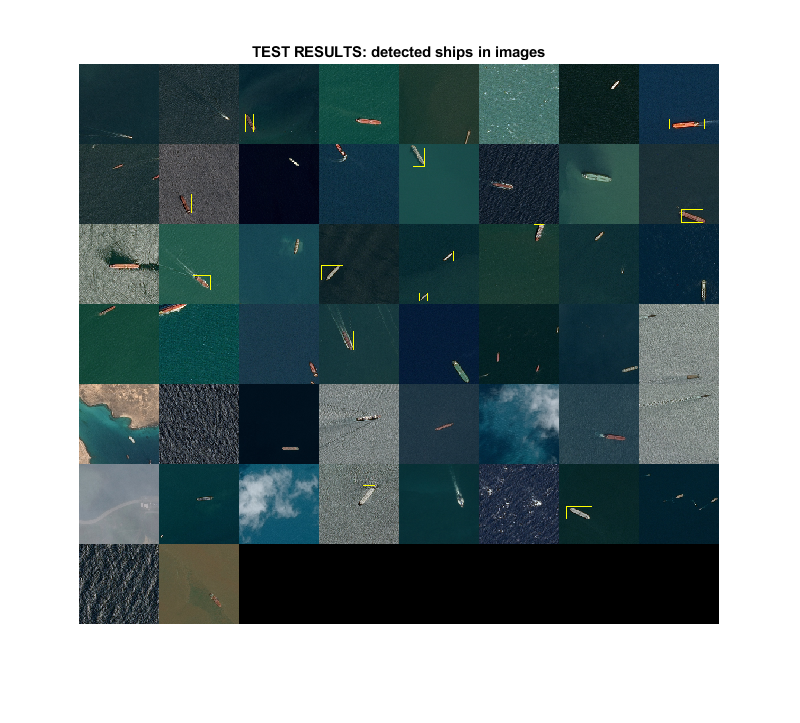

clear annotated* image*

% read TEST images and detect ships
d = dir(testFolder);
k = 0;
for n = 1:length(d)
  f = d(n).name;
  try 
    image = imread([testFolder f]);
    image2 = imresize(image,inputSize(1:2));
    detectionResult = detect(detector, image2);
    annotatedImage = insertShape(image2,'Rectangle',detectionResult);
    % collect images to show
    k = k+1;
    annotatedIMAGES{k} = annotatedImage;
  end
end
N_test = k; % number of test images

% show annotated images
figure
montage(annotatedIMAGES)
title('TEST RESULTS: detected ships in images')

### Show ship detection on individual test images

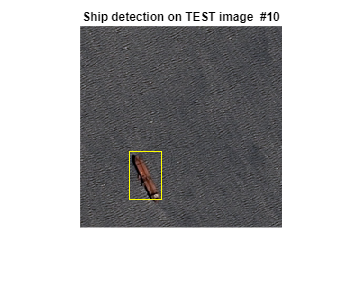

% show selected transformed image
pick_image = 10;

imshow(annotatedIMAGES{pick_image})
title(['Ship detection on TEST image  #' num2str(pick_image)])

## Conclusions

This example presents the step-by-step development of a deep learning solution for the detection of ships on satellite images. The solution approach is quite general and can be adapted to different domain areas, similarly as this case study was adopted from an earlier MATLAB application of [Object Detection Using YOLO v2 Deep Learning](https://www.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v2.html). A few conclusions and takeaways can be summarized:

- The trained YOLO network already successfully detects several ships in satellite images, although some ships on test images are not detected.

- Training data set of only 100 ship images is too small to train a fully functional ship detector, but by using the transfer learning approach, the required number of images is much smaller than what is required for the 'from-scratch' deep learning approach. 

- The example presents the potential workflow toward the solution, and in practice, many more annotated images (in order of hundreds or thousands of images) should be provided to train a detector with good detection accuracy.

## Products used

Display products used in this example:

license inuse

image_toolbox
matlab
neural_network_toolbox
video_and_image_blockset


## Functions

function data = preprocessData(data,targetSize)
  % Resize image the targetSize
  sz      = size(data{1},[1 2]);
  scale   = targetSize(1:2)./sz;
  data{1} = imresize(data{1},targetSize(1:2));
  % Resize boxes to new image size
  data{2} = bboxresize(data{2},scale);
end